%% EEE 4631: Power System III - CEP Implementation
% Economic Load Dispatch (ELD) and Economic Emission Dispatch (EED)
% For a thermal power plant with N generators (3 ≤ N ≤ 6)

clc;
clear;
close all;

%% Problem Data and Assumptions
% Assume a 5-generator system with total demand of 850 MW
N = 5; % Number of generators
Pd = 850; % Total demand in MW

% Generator limits (MW) [Pmin, Pmax]
gen_limits = [100 300;  % G1
              50  200;  % 2
              80  250;  % G3
              70  180;  % G4
              60  150]; % G5

% Fuel cost coefficients: a, b, c ($/hr)
% Format: [a b c] for cost function: F(P) = a*P^2 + b*P + c
cost_coeff = [0.0040 2.00 100;  % Generator 1
              0.0025 1.75 120;  % Generator 2
              0.0050 2.50 80;   % Generator 3
              0.0035 2.25 90;   % Generator 4
              0.0045 2.10 110]; % Generator 5

% Emission coefficients: α, β, γ, η, δ (kg/hr)
% Format: [α β γ η δ] for emission function: 
% E(P) = α*P^2 + β*P + γ + η*exp(δ*P)
emission_coeff = [0.00025 0.025 0.5 0.05 0.01;  % G1
                  0.00020 0.020 0.4 0.04 0.01;  % G2
                  0.00030 0.030 0.6 0.06 0.01;  % G3
                  0.00022 0.022 0.5 0.05 0.01;  % G4
                  0.00028 0.028 0.5 0.05 0.01]; % G5



%% Solve the Optimization Problems

% Initial guess (equal distribution of load)
P0 = ones(1, N) * Pd / N;

% Constraints: Power balance and generator limits
A = [];
b = [];
Aeq = ones(1, N);
beq = Pd;
lb = gen_limits(:, 1)';
ub = gen_limits(:, 2)';
nonlcon = [];

% Optimization options
options = optimoptions('fmincon', 'Display', 'iter', 'Algorithm', 'interior-point');

% (a) Solve ELD - Minimize fuel cost
disp('Solving Economic Load Dispatch (ELD)...');

Solving Economic Load Dispatch (ELD)...


[P_eld, fval_eld] = fmincon(@(P) fuel_cost(P, cost_coeff), P0, A, b, Aeq, beq, lb, ub, nonlcon, options);

Your initial point x0 is not between bounds lb and ub; FMINCON
shifted x0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.791339e+03    2.099e+01    8.037e-01
    1      12    2.809598e+03    1.554e+01    8.044e-01    2.457e+00
    2      18    2.860696e+03    0.000e+00    8.309e-01    8.071e+00
    3      24    2.859329e+03    0.000e+00    8.225e-01    1.210e+00
    4      30    2.852486e+03    0.000e+00    7.815e-01    6.290e+00
    5      36    2.828495e+03    1.137e-13    6.542e-01    2.434e+01
    6      43    2.828423e+03    0.000e+00    5.029e-01    8.427e-02
    7      49    2.825920e+03    0.000e+00    2.765e-01    5.347e+00
    8      55    2.824592e+03    1.137e-13    2.698e-01    2.983e+00
    9      61    2.823465e+03    1.137e-13    2.679e-01    2.667e+00
   10      67    2.819902e+03    0.000e+00    2.679e-01    1.080e+01
   11    

cost_eld = fuel_cost(P_eld, cost_coeff);

emission_eld = total_emission(P_eld, emission_coeff);

% (b) Solve EED - Minimize emission
disp('Solving Economic Emission Dispatch (EED)...');

Solving Economic Emission Dispatch (EED)...


[P_eed, fval_eed] = fmincon(@(P) total_emission(P, emission_coeff), P0, A, b, Aeq, beq, lb, ub, nonlcon, options);

Your initial point x0 is not between bounds lb and ub; FMINCON
shifted x0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    5.872906e+01    2.099e+01    2.535e-02
    1      12    5.932673e+01    1.558e+01    2.605e-02    2.422e+00
    2      18    6.105468e+01    1.137e-13    2.853e-02    7.879e+00
    3      24    6.105367e+01    0.000e+00    2.292e-02    4.177e-02
    4      30    6.104470e+01    0.000e+00    2.281e-02    4.190e-01
    5      36    6.103246e+01    0.000e+00    2.266e-02    5.279e-01
    6      42    6.092103e+01    0.000e+00    2.196e-02    5.200e+00
    7      48    6.080939e+01    1.137e-13    2.196e-02    5.959e+00
    8      54    6.053600e+01    1.137e-13    1.485e-02    2.609e+01
    9      60    6.061826e+01    1.137e-13    1.476e-02    1.210e+01
   10      66    6.057166e+01    0.000e+00    1.533e-02    5.362e+00
   11    

cost_eed = fuel_cost(P_eed, cost_coeff);
emission_eed = total_emission(P_eed, emission_coeff);

% (c) Solve combined dispatch with different weights
weights = [0.3, 0.5, 0.7]; % Different weight combinations
P_combined = zeros(length(weights), N);
cost_combined = zeros(length(weights), 1);
emission_combined = zeros(length(weights), 1);

disp('Solving Combined Economic-Emission Dispatch...');

Solving Combined Economic-Emission Dispatch...


for i = 1:length(weights)
    weight = weights(i);
    [P_temp, fval_temp] = fmincon(@(P) combined_objective(P, cost_coeff, emission_coeff, weight),...
        P0, A, b, Aeq, beq, lb, ub, nonlcon, options);
    P_combined(i, :) = P_temp;
    cost_combined(i) = fuel_cost(P_temp, cost_coeff);
    emission_combined(i) = total_emission(P_temp, emission_coeff);
end

Your initial point x0 is not between bounds lb and ub; FMINCON
shifted x0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    1.248505e-01    2.099e+01    4.161e-05
    1      12    1.258221e-01    1.558e+01    4.243e-05    2.420e+00
    2      18    1.286337e-01    0.000e+00    4.537e-05    7.881e+00
    3      24    1.286339e-01    0.000e+00    4.538e-05    3.209e-02
    4      30    1.286355e-01    0.000e+00    4.547e-05    3.784e-01
    5      36    1.286368e-01    0.000e+00    4.555e-05    2.985e-01
    6      42    1.286369e-01    0.000e+00    4.555e-05    1.540e-02
    7      48    1.286369e-01    1.137e-13    4.262e-05    1.962e-03
    8      54    1.286368e-01    1.137e-13    4.262e-05    1.024e-02
    9      60    1.286365e-01    0.000e+00    4.261e-05    4.962e-02
   10      66    1.286352e-01    1.137e-13    4.254e-05    2.105e-01
   11    


%% Display Results
fprintf('\n=== RESULTS ===\n');


=== RESULTS ===


fprintf('Total Demand: %.2f MW\n\n', Pd);

Total Demand: 850.00 MW




% ELD Results
fprintf('(a) ECONOMIC LOAD DISPATCH (ELD) - Minimizing Fuel Cost:\n');

(a) ECONOMIC LOAD DISPATCH (ELD) - Minimizing Fuel Cost:


fprintf('Generator Allocations (MW):\n');

Generator Allocations (MW):


for i = 1:N
    fprintf('  Generator %d: %.2f MW\n', i, P_eld(i));
end

  Generator 1: 205.56 MW
  Generator 2: 200.00 MW
  Generator 3: 114.44 MW
  Generator 4: 180.00 MW
  Generator 5: 150.00 MW


fprintf('Total Fuel Cost: $%.2f/hr\n', cost_eld);

Total Fuel Cost: $2816.37/hr


fprintf('Total Emission: %.2f kg/hr\n\n', emission_eld);

Total Emission: 60.55 kg/hr




% EED Results
fprintf('(b) ECONOMIC EMISSION DISPATCH (EED) - Minimizing Emission:\n');

(b) ECONOMIC EMISSION DISPATCH (EED) - Minimizing Emission:


fprintf('Generator Allocations (MW):\n');

Generator Allocations (MW):


for i = 1:N
    fprintf('  Generator %d: %.2f MW\n', i, P_eed(i));
end

  Generator 1: 178.62 MW
  Generator 2: 200.00 MW
  Generator 3: 141.38 MW
  Generator 4: 180.00 MW
  Generator 5: 150.00 MW


fprintf('Total Fuel Cost: $%.2f/hr\n', cost_eed);

Total Fuel Cost: $2822.90/hr


fprintf('Total Emission: %.2f kg/hr\n\n', emission_eed);

Total Emission: 60.13 kg/hr




% Combined Results
fprintf('(c) COMBINED ECONOMIC-EMISSION DISPATCH:\n');

(c) COMBINED ECONOMIC-EMISSION DISPATCH:


for i = 1:length(weights)
    fprintf('Weight %.1f (Cost) : %.1f (Emission)\n', weights(i), 1-weights(i));
    fprintf('Generator Allocations (MW):\n');
    for j = 1:N
        fprintf('  Generator %d: %.2f MW\n', j, P_combined(i, j));
    end
    fprintf('Total Fuel Cost: $%.2f/hr\n', cost_combined(i));
    fprintf('Total Emission: %.2f kg/hr\n\n', emission_combined(i));
end

Weight 0.3 (Cost) : 0.7 (Emission)


Generator Allocations (MW):


  Generator 1: 189.46 MW
  Generator 2: 199.99 MW
  Generator 3: 130.64 MW
  Generator 4: 179.97 MW
  Generator 5: 149.94 MW


Total Fuel Cost: $2818.75/hr


Total Emission: 60.20 kg/hr



Weight 0.5 (Cost) : 0.5 (Emission)


Generator Allocations (MW):


  Generator 1: 195.06 MW
  Generator 2: 199.99 MW
  Generator 3: 125.01 MW
  Generator 4: 179.97 MW
  Generator 5: 149.96 MW


Total Fuel Cost: $2817.39/hr


Total Emission: 60.29 kg/hr



Weight 0.7 (Cost) : 0.3 (Emission)


Generator Allocations (MW):


  Generator 1: 199.78 MW
  Generator 2: 199.99 MW
  Generator 3: 120.29 MW
  Generator 4: 179.97 MW
  Generator 5: 149.97 MW


Total Fuel Cost: $2816.69/hr


Total Emission: 60.39 kg/hr




%% Comparative Analysis
fprintf('(d) COMPARATIVE ANALYSIS:\n');

(d) COMPARATIVE ANALYSIS:


fprintf('Comparison between ELD and EED:\n');

Comparison between ELD and EED:


fprintf('  Cost Increase in EED compared to ELD: $%.2f/hr (%.2f%%)\n',...
    cost_eed - cost_eld, (cost_eed - cost_eld)/cost_eld*100);

  Cost Increase in EED compared to ELD: $6.53/hr (0.23%)


fprintf('  Emission Reduction in EED compared to ELD: %.2f kg/hr (%.2f%%)\n\n',...
    emission_eld - emission_eed, (emission_eld - emission_eed)/emission_eld*100);

  Emission Reduction in EED compared to ELD: 0.42 kg/hr (0.69%)




fprintf('Trade-off Analysis:\n');

Trade-off Analysis:


for i = 1:length(weights)
    cost_increase = cost_combined(i) - cost_eld;
    emission_reduction = emission_eld - emission_combined(i);
    fprintf('  Weight %.1f: Cost increase $%.2f/hr, Emission reduction %.2f kg/hr\n',...
        weights(i), cost_increase, emission_reduction);
end

  Weight 0.3: Cost increase $2.37/hr, Emission reduction 0.35 kg/hr
  Weight 0.5: Cost increase $1.02/hr, Emission reduction 0.26 kg/hr
  Weight 0.7: Cost increase $0.32/hr, Emission reduction 0.16 kg/hr


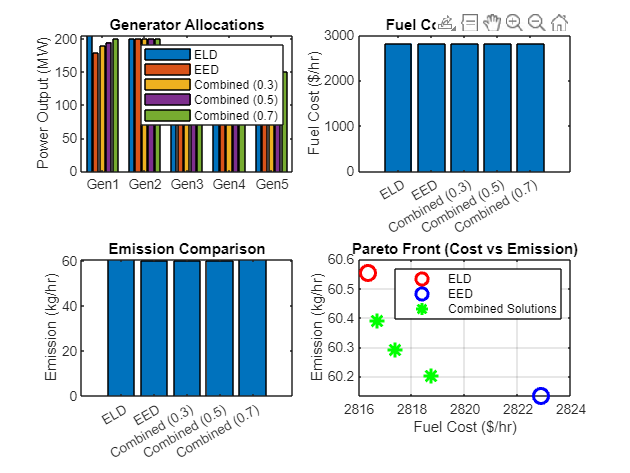


(e) SOCIETAL AND HEALTH IMPACTS DISCUSSION:


The ELD solution minimizes cost but results in higher emissions,


which contributes to air pollution and associated health problems.


The EED solution reduces emissions but increases operational costs,


which may lead to higher electricity prices for consumers.



Health impacts of power plant emissions include:


- Respiratory diseases (asthma, bronchitis)


- Cardiovascular problems


- Increased risk of cancer


- Neurological effects



Societal impacts include:


- Healthcare costs associated with pollution-related illnesses


- Environmental degradation


- Climate change contributions


- Economic impacts from both healthcare and environmental costs



The combined approach offers a balanced solution that considers


both economic and environmental factors, representing a more


sustainable approach to power system operation.



%% Visualization
figure;

% Subplot 1: Generator allocations
subplot(2, 2, 1);
bar([P_eld; P_eed; P_combined]');
set(gca, 'XTickLabel', {'Gen1', 'Gen2', 'Gen3', 'Gen4', 'Gen5'});
ylabel('Power Output (MW)');
title('Generator Allocations');
legend('ELD', 'EED', 'Combined (0.3)', 'Combined (0.5)', 'Combined (0.7)');

% Subplot 2: Cost comparison
subplot(2, 2, 2);
costs = [cost_eld, cost_eed, cost_combined'];
bar(costs);
ylabel('Fuel Cost ($/hr)');
set(gca, 'XTickLabel', {'ELD', 'EED', 'Combined (0.3)', 'Combined (0.5)', 'Combined (0.7)'});
title('Fuel Cost Comparison');

% Subplot 3: Emission comparison
subplot(2, 2, 3);
emissions = [emission_eld, emission_eed, emission_combined'];
bar(emissions);
ylabel('Emission (kg/hr)');
set(gca, 'XTickLabel', {'ELD', 'EED', 'Combined (0.3)', 'Combined (0.5)', 'Combined (0.7)'});
title('Emission Comparison');

% Subplot 4: Pareto front (cost vs emission)
subplot(2, 2, 4);
plot(cost_eld, emission_eld, 'ro', 'MarkerSize', 10, 'LineWidth', 2);
hold on;
plot(cost_eed, emission_eed, 'bo', 'MarkerSize', 10, 'LineWidth', 2);
plot(cost_combined, emission_combined, 'g*', 'MarkerSize', 10, 'LineWidth', 2);
xlabel('Fuel Cost ($/hr)');
ylabel('Emission (kg/hr)');
title('Pareto Front (Cost vs Emission)');
legend('ELD', 'EED', 'Combined Solutions');
grid on;

%% Optimization Problem Setup

% (a) Economic Load Dispatch (ELD) - Minimize fuel cost only

function cost = fuel_cost(P, cost_coeff)
    % Calculate total fuel cost
    cost = 0;
    for i = 1:size(cost_coeff, 1)
        a = cost_coeff(i, 1);
        b = cost_coeff(i, 2);
        c = cost_coeff(i, 3);
        cost = cost + a*P(i)^2 + b*P(i) + c;
    end
end

% (b) Economic Emission Dispatch (EED) - Minimize emission only
function emission = total_emission(P, emission_coeff)
    % Calculate total emission
    emission = 0;
    for i = 1:size(emission_coeff, 1)
        alpha = emission_coeff(i, 1);
        beta = emission_coeff(i, 2);
        gamma = emission_coeff(i, 3);
        eta = emission_coeff(i, 4);
        delta = emission_coeff(i, 5);
        emission = emission + alpha*P(i)^2 + beta*P(i) + gamma + eta*exp(delta*P(i));
    end
end

% (c) Combined dispatch - Multi-objective optimization
function f = combined_objective(P, cost_coeff, emission_coeff, weight)
    % Weighted sum approach for multi-objective optimization
    cost = fuel_cost(P, cost_coeff);
    emission = total_emission(P, emission_coeff);
    
    % Normalize the objectives (simple normalization for demonstration)
    % In practice, you might use more sophisticated normalization
    norm_cost = cost / 10000;
    norm_emission = emission / 1000;
    
    f = weight * norm_cost + (1 - weight) * norm_emission;
end